## Load Pretrained DnCNN network

netpath = fullfile('..','latest_net.mat');
load(netpath,'net'); % or use DenoisingNetwork('dncnn') to load pretrained network

## Load test image

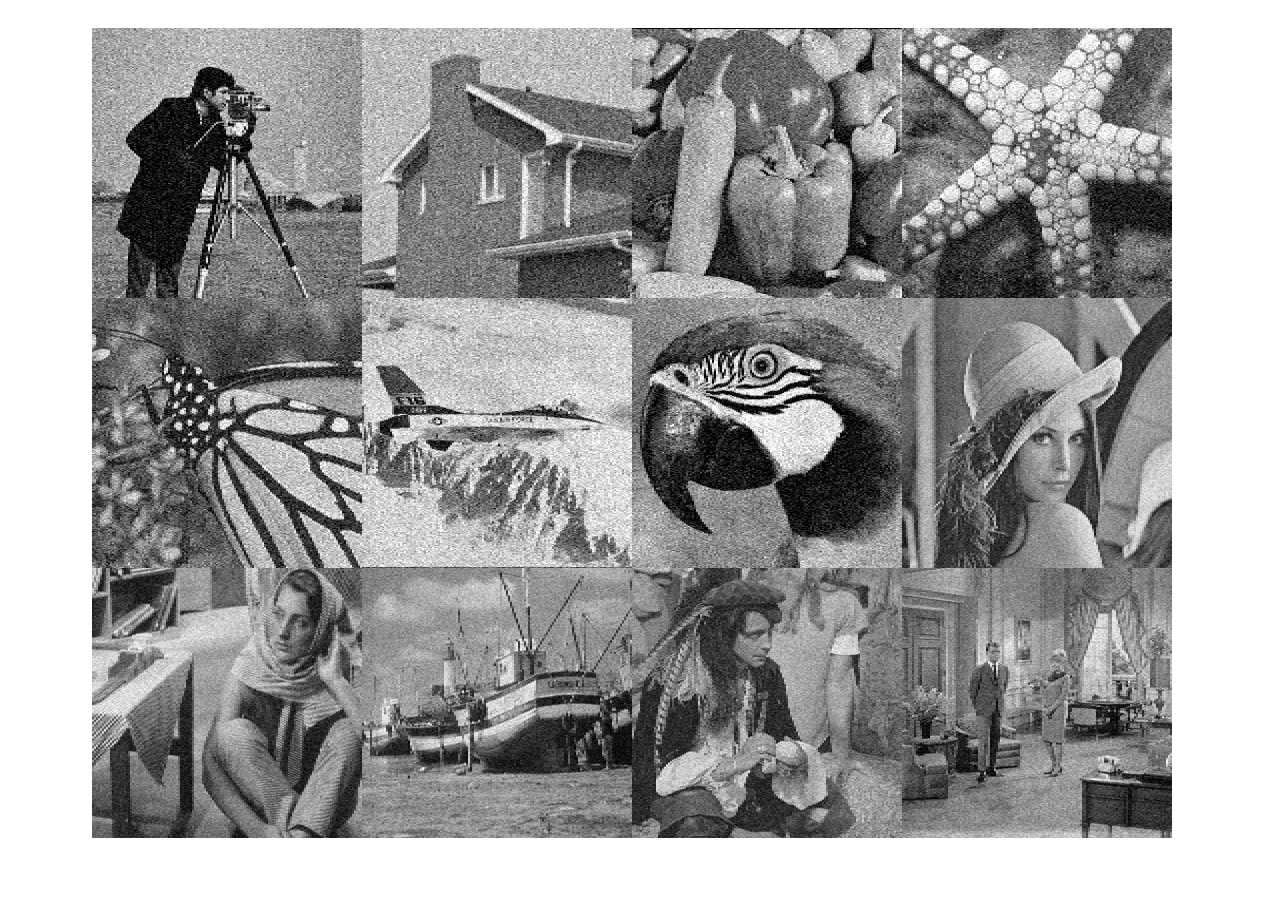

datapath = fullfile('..','Data','Test','Set12');
noisy_imds = imageDatastore(datapath,...
    'ReadFcn',@(filename) imnoise(im2single(imread(filename)),'gaussian',0,0.01));
montage(noisy_imds.readall())

## Denoise Images

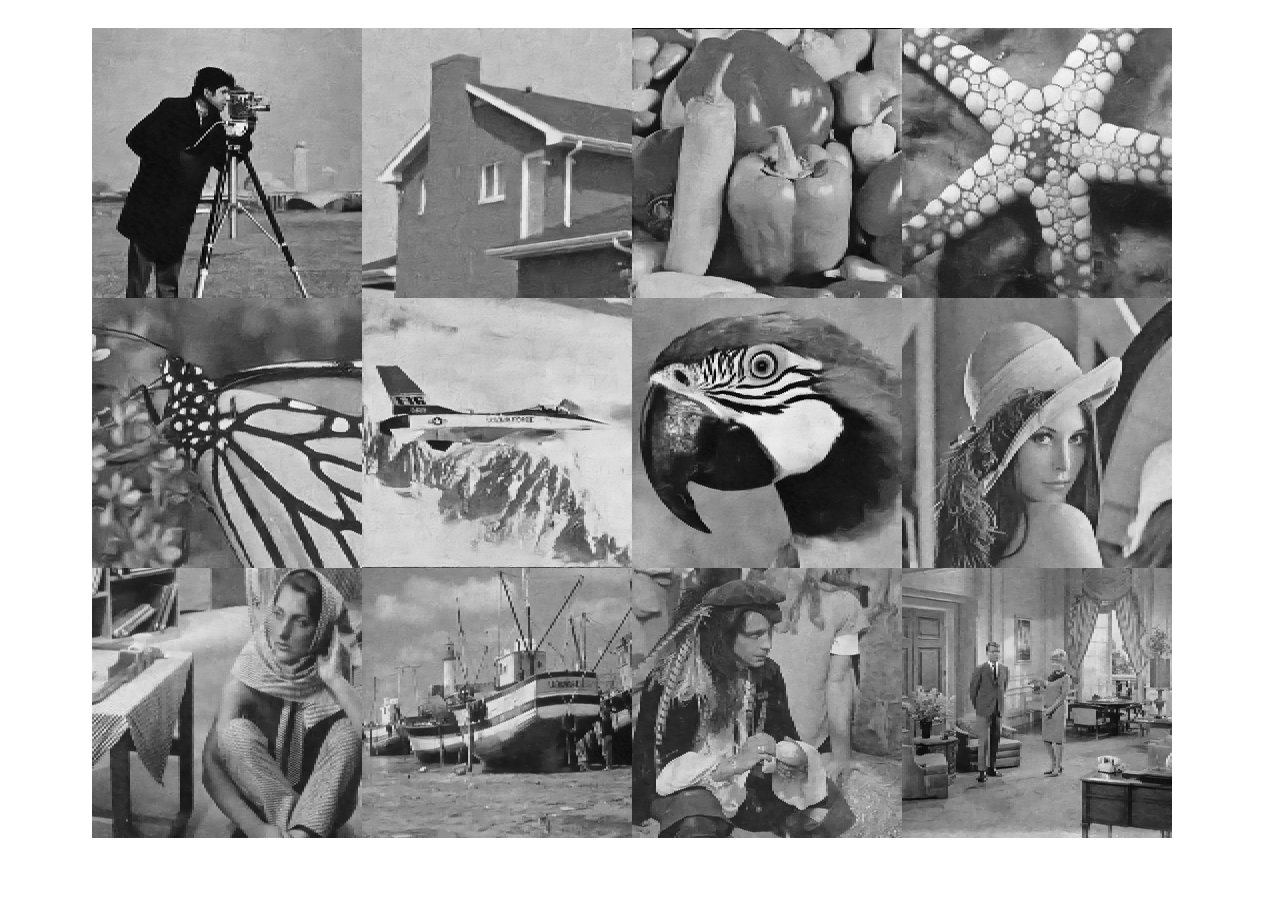

denoised_imgs = cellfun(@(x)denoiseImage(x,net),noisy_imds.readall(),'UniformOutput',false);
montage(denoised_imgs);